# Check Angle Criterion for arbitrary Point lies on the Root Locus

% Only use for positive imaginary part as root locus mirors around x-axis
clear

## Generate System as transfer function and Point to be checked

s = tf('s');


% Examples:
G = (s+1)*(s-2)*(s+5)/(s+10)/(s+1+3i)/(s+1-3i);
G= 4/(s^2+2*0.2*4*s+16)*(s+0);

%G= 1/(s-1);
%G= 4/(s^2+2*0.2*4*s+16);
% G= 1/(s+6)/(s+1)/(s+1+j)/(s+1-j);
% 
% G = tf(1,1);
% ord  =2;
% for i = 1:ord
% G = G /(s+i);
% end

%G= G*(s-2);
%G = 1/(s+1);

% Define Testpoint to be checked if on RL:
A = -2.4 + 3.2j;
A = -2;

## Pole Zero Map

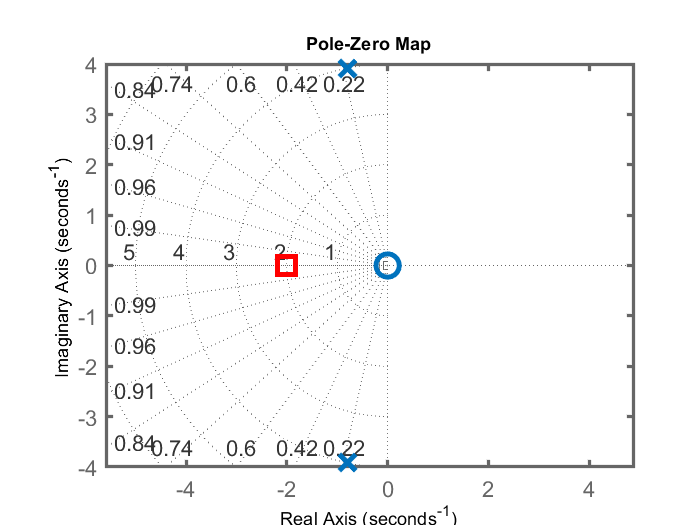

A = real(A) + j*abs(imag(A));

clear leg
figure(1); pzmap(G); hold on;
axis equal; grid on, plot(real(A),imag(A),'sr')

% Visuals:
h=gca; h.LineWidth = 2; h.FontSize =13;
h.Children(1).MarkerSize =14;
h.Children(1).LineWidth =3;

num = length(h.Children(1).Children);
h.Children(2).Children(1).LineWidth = 3;
h.Children(2).Children(1).MarkerSize =14;
h.Children(2).Children(2).LineWidth = 3;
h.Children(2).Children(2).MarkerSize =14;
xlim([min(h.XLim(1),real(A)), max(h.XLim(2),real(A))])
ylim([min(h.YLim(1),imag(A)), max(h.YLim(2),imag(A))])
axis equal

## Calculation of Angle Criterion:

% System zeros
 z = zero(G)

z = 0

% System poles
p = pole(G)

p =   -0.8000 + 3.9192i
  -0.8000 - 3.9192i


% Angle contribution of poles
for i = 1:length(p)  
    % Calculate angles simply by absolue distances between pole and A
    p_angle(i) =   180/pi * atan( ( abs(imag(p(i))-imag(A)))/  (abs(real(p(i))-real(A))));
    
    % Correct angles depnding on Quadrant
    if real(p(i)) >real(A)
        if imag(p(i)) >=imag(A)
            p_angle(i) = p_angle(i)+180;
            %Q=1
        else
            p_angle(i) = 180-p_angle(i);
            %Q=4
        end
    else
        if imag(p(i)) > imag(A)
            p_angle(i) = 360-p_angle(i);
            %Q=2
        else 
            %Q=3
        end
        
    end
    disp('%%%%')
    
end

%%%%
%%%%


try 
    disp('Individual angle for each pole:')
    p_angle
end

Individual angle for each pole:


p_angle =   252.9761  107.0239


% Pase contribution of zeros
for i = 1:length(z)  
    % Calculate angles simply by absolue distances between pole and A
    z_angle(i) =   180/pi * atan( ( abs(imag(z(i))-imag(A)))/  (abs(real(z(i))-real(A))));
    
    % Correct angles depnding on Quadrant
    if real(z(i)) >real(A)
        if imag(z(i)) >=imag(A)
            z_angle(i) = z_angle(i)+180;
            %Q=1
        else
            z_angle(i) = 180-z_angle(i);
            %Q=4
        end
    else
        if imag(p(i)) > imag(A)
            z_angle(i) = 360-z_angle(i);
            %Q=2
        end
        
    end
    %disp('%%%%')
    
end
try 
    disp('Individual angle for each zero:')
        z_angle
catch
    z_angle=0;
end

Individual angle for each zero:


z_angle = 180


% Calculate Phase Criterion
Theta = sum(z_angle) - sum(p_angle);

% Bring into the range of ]-360,0]
while Theta<=-360
    Theta = Theta+360;
end
while Theta>0
    Theta = Theta-360;
end

disp(['Resulting angle within ]-360,0]deg of the angle criterion: ', num2str(Theta)])

Resulting angle within ]-360,0]deg of the angle criterion: -180


if round(Theta)==Theta == -180
    disp('Point can be reached with positive gain!' )
elseif Theta == 0
    disp('Point can be reached with negative gain!' )
else
    disp('Point cannot be reached with real gain!' )
end

Point cannot be reached with real gain!


## Visualization Check: Plot Root Locus Plot & Point together

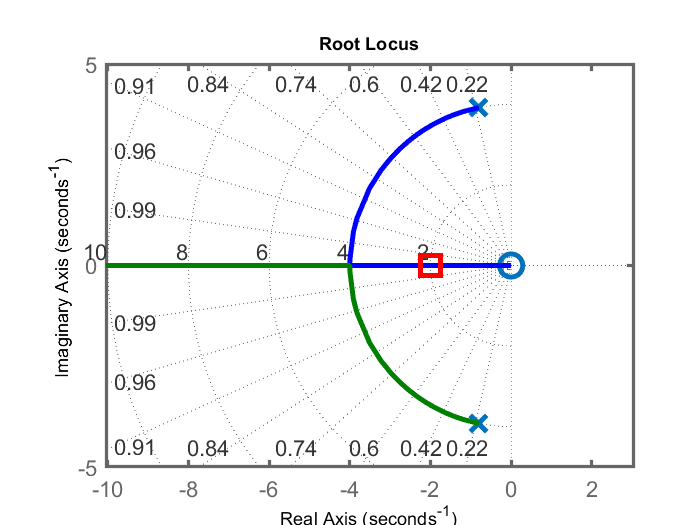

figure(2); rlocus(G); hold on; grid on
h=gca; h.LineWidth = 2; h.FontSize =13;

num = length(h.Children(1).Children);

%Visuals
for i = 1:num
    h.Children(1).Children(i).MarkerSize =14;
    h.Children(1).Children(i).LineWidth =3;
    h.Children(1).Children(i).MarkerSize =14;
    h.Children(1).Children(i).LineWidth =3;
end
plot(real(A),imag(A),'sr','Linewidth',3, 'MarkerSize',15)
xlim([min(h.XLim(1),real(A)), max(h.XLim(2),real(A))])
ylim([min(h.YLim(1),imag(A)), max(h.YLim(2),imag(A))])
axis equal

## Calculate Gain

Theta = round(Theta);
if Theta == -180 || Theta == 0
    % Calculate distance to point from poles
    for i = 1:length(p)  
        p_dist(i) =   sqrt((imag(p(i))-imag(A))^2 +(real(p(i))-real(A))^2);
    end
    
    % Calculate distance to point from zeros
    if isempty(z)
        z_dist = [];
    else
        for i = 1:length(z)  
            z_dist(i) =   sqrt((imag(z(i))-imag(A))^2 +(real(z(i))-real(A))^2);
        end
    end
    disp(['Individal distances for each pole: ',num2str(p_dist)])   
    disp(['Individal distances for each pole: ',num2str(z_dist)]) 
    
    
    % Calculate total gain:
    K = prod(p_dist)/prod(z_dist); % note this equation is already inverted
    
    % negative is angle criterion is 0
    if Theta == 0
        K = -K;   
    end
    
    % Calculate gain from plant
    [~,~,K0] = zpkdata(G);
    disp(['Plant Gain K0 = G(0) = : ',num2str(K0)]) 
    
    % Calculate controller feedback gain
    Kr = K/K0;
    disp('');disp(['Resulting controller gain via Kr = K/K0 =  ',num2str(Kr)]) 
    
    % Check via new cosed Loop Poles; one CL Pole needs to correspond to A!

        disp(newline)
        P_cl = rlocus(G*Kr,1);
        disp(['Chosen point to be checked:  ', num2str(A)])

        disp(['Closed loop poles with calulcated feedback gain:  ', num2str(P_cl')])
        
        disp(['Check if one pole corresponds to point A (difference needs to be 0):  ', num2str(min(abs(P_cl - A)))])

    
else
    disp('Point cannot be reached with real gain, thus no gain calculated')
end

Individal distances for each pole: 4.0988      4.0988


Individal distances for each pole: 2


Plant Gain K0 = G(0) = : 4


Resulting controller gain via Kr = K/K0 =  2.1


Chosen point to be checked:  -2


Closed loop poles with calulcated feedback gain:  -8          -2


Check if one pole corresponds to point A (difference needs to be 0):  8.8818e-16
